# Optmisation Dynamique - TP 03, 05/01/2023

Fait en matlab R2020a.

binôme :

- Déric Augusto França de Sales

- Michelle Ferreira Martins

clc; clear all; close all;

## Definition of parameters

global Vo Vi R L C Q Qf rho T N h beta k_max A1 A2 B1 B2 x_ref s_ref t

Vo = 15;
Vi = 10;
R = 20;
L = 0.3;
C = 0.1;
Q = eye(2);
Qf = Q;
rho = 1;
T = 5;
N = 100;
h = T/N;
epsilon = 10^(-6);
beta = 0.5;
k_max = 25;
t = linspace(0, T, N);

Calculation of duty cycle

% La formule for buck-boost is defined

s_ref = Vo/(Vo + Vi);

Calculation of the corresponding current

il = Vo/(R*(1-s_ref));

x_ref = [il; Vo];

Matrices

A1 = [0, 0; 0, -1/(R*C)];
A2 = [0, -1/L; 1/C, -1/(R*C)];
B1 = [1/L; 0];
B2 = [0; 0];

## Algorithm FBS

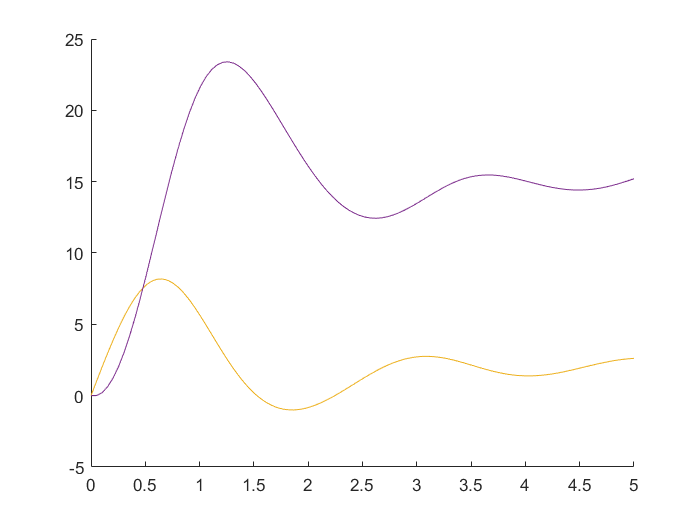

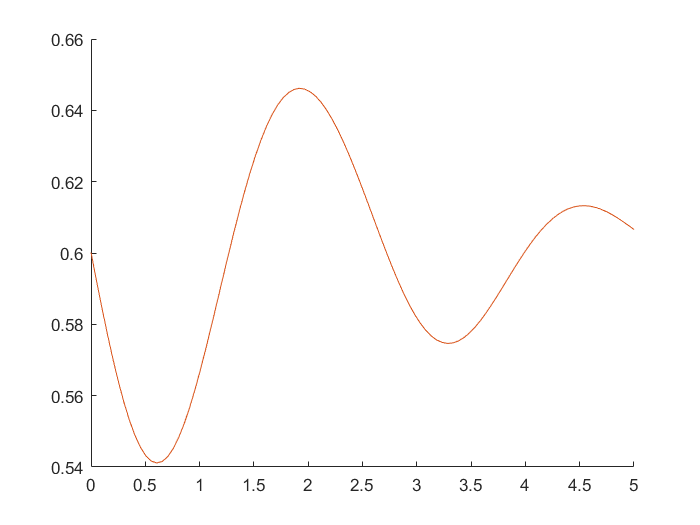

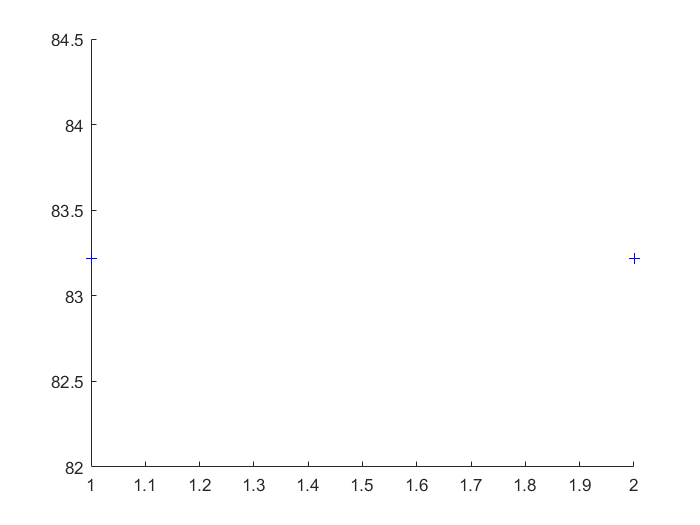

s = s_ref*ones(1, N);

X = discretX(s);

J_old = 0;
s_old = s_ref;
p = 1;
Test = true;

while Test && p < 100

    X = discretX(s);
    lbd = discretLambda(X, s);
    v = discretV(X, lbd);
    
    [X_min, s_min, J_min] = minimisation(X, s, v);
    
    figure(1)
    hold on
    plot(t, X_min(1, :), t, X_min(2, :))
    figure(2)
    hold on
    plot(t, s_min)
    figure(3)
    hold on
    plot(p, J_min, '+b')
    
    Test = (abs(J_old - J_min) > 1e-3) || (abs(J_old - J_min) > 10^(-6));
    J_old = J_min;
    s_old = s_min;
    p = p + 1;
    
end